close all
ki=datab(:,1);
pi=datab(:,2);
SE=zeros(1,numel(pi));
for i=1:numel(pi)
    SE(i)=sqrt(sum((ki(i) - pi(i)).^ 2));
end
ymin=min(SE)

ymin =        0.00958921582639349


xmin=pi(SE==ymin)

xmin =           1.19589267574329


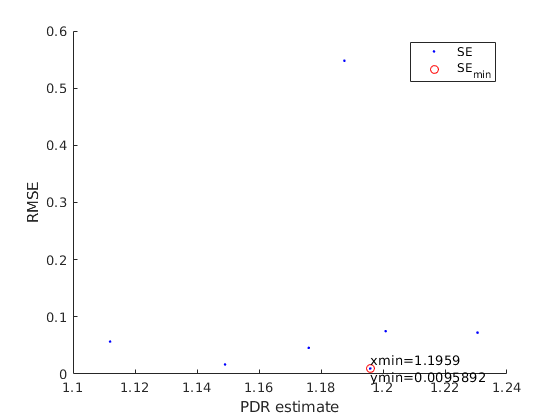

hold on
plot(pi,SE,'b.')
plot(xmin,ymin,'ro')
text(xmin,ymin,['xmin=' num2str(xmin) char(10) 'ymin=' num2str(ymin)])
xlabel('PDR estimate'),ylabel('RMSE'),legend('SE','SE_{min}')

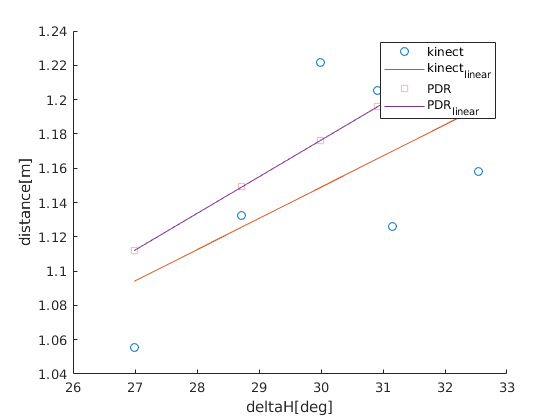

init = 2;


y=datab(init:end,1);
y1=datab(init:end,2);
x=deltaH(init:end,1);
N=length(x);

p=polyfit(x,y,1);
xx=x;
yy=polyval(p,xx);
figure,hold on
plot(x,y,'o',xx,yy)

%  title(num2str(p))
xlabel('deltaH[deg]'),ylabel('distance[m]')
p1=polyfit(x,y1,1);
yy1=polyval(p1,xx);
plot(x,y1,'s','Color',[1,.7,.7])
plot(x,yy1)
legend('kinect','kinect_{linear}','PDR','PDR_{linear}')


for i=1:N
xbar=mean(x(1:i,1));
ybar=mean(y(1:i,1));

xybars = mean(x(1:i,1).*y(1:i,1));
xs = mean(y(1:i,1).^2);

end
m=((xbar.*ybar)-xybars)/((xbar).^2-xs)

m =      -6.49211194961056e-05


b=ybar-m.*xbar

b =           1.15177413815467


% end

% end
figure
hold on
plot(x,datab(init:end,2),'o');
plot(x,y,'o');

%  y=fit.coeff(1,1)*x+fit.coeff(1,2);
%  plot(x,y);

yy=m*x+b;
plot(x,yy);
%
 legend('PDR','kinect','kinect_{fit}','minSE');

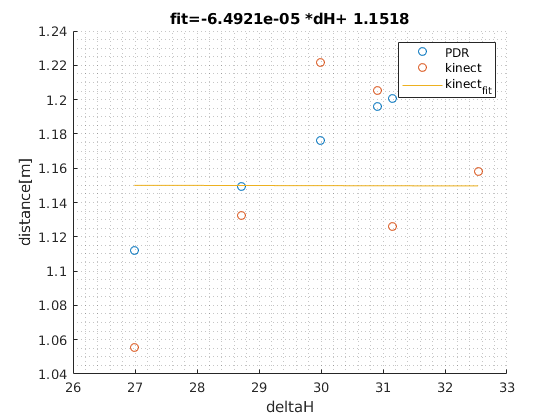

xlabel('deltaH'),ylabel('distance[m]'),
title(['fit=',num2str(m),' *dH+ ',num2str(b)])
grid minor